%パラメータ設定
numNode = 20; %ノード数
completeGraph = complete_graph(numNode); %N_node個のノードを持つ完全グラフ
adjacencyMatrix = adjacency(completeGraph); %completeGraphの隣接行列
omega = 3; %固有振動数
dencityBetweenNodes = 8; %ノード間の結合密度
activeNode = 1; %活性ノードの自己振幅係数
inactiveNode = -1; %不活性ノードの自己振幅係数
t_max = 60;
dt = 0.05;
t_steps = t_max / dt;
t = linspace(0, t_max, t_steps);
ntrans = 600; %過渡期
t_span = [0 t_max];
z_initial = ones(numNode, 1) + 1i * zeros(numNode, 1); %初期値 1 + 0*i
z_initial = [real(z_initial); imag(z_initial)]';
dim = numNode*2; %ノード数の実部と虚部

    0.9865



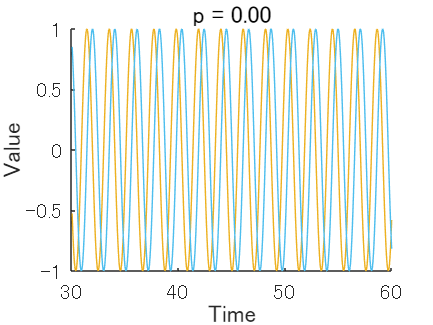

    0.8999



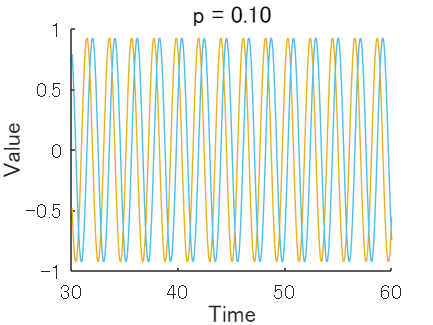

    0.7990



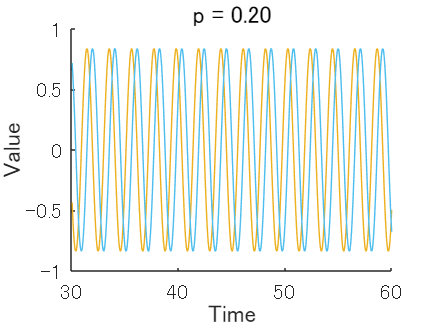

    0.6814



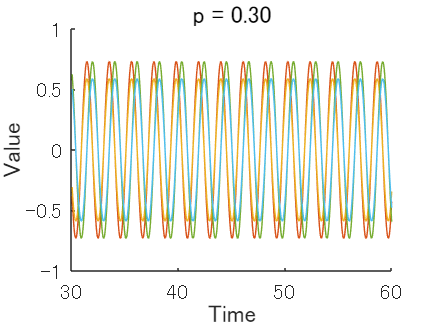

    0.5384



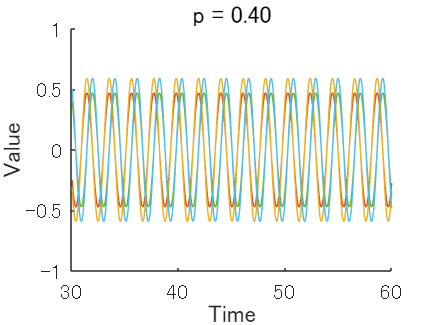

    0.3352



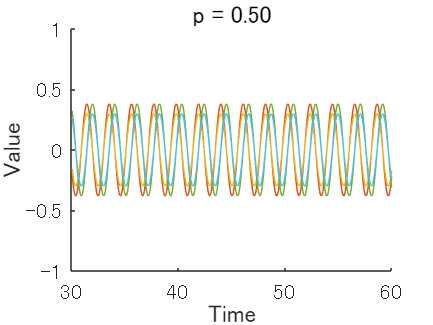

    0.0027



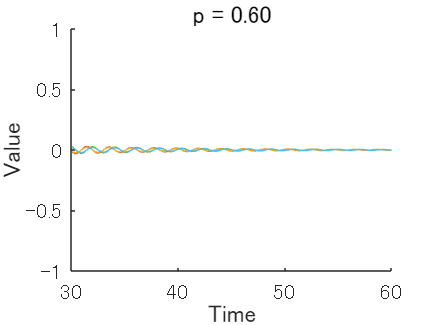

   1.9279e-08



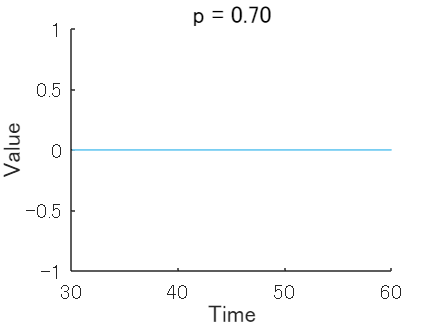

   1.4543e-08



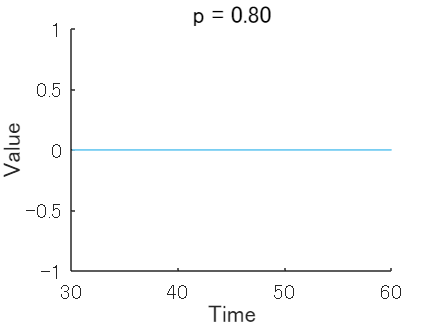

   2.6489e-08



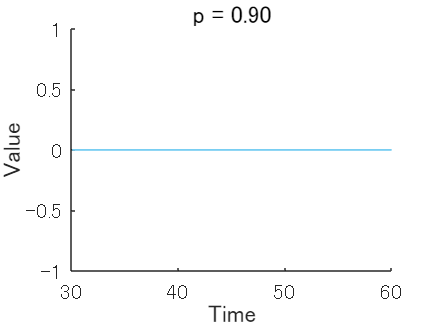

   3.0335e-07



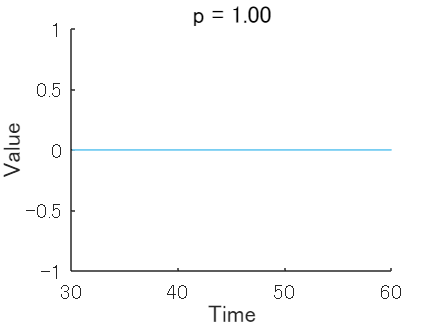

% 時間ベクトル（横軸）
time = t(ntrans + 1:end); % 過渡期以降の時間

for p = 0:0.1:1
    z_data = solve_model(t_steps, ntrans, dim, t, p, numNode, ...
    activeNode, inactiveNode, z_initial, omega, dencityBetweenNodes, adjacencyMatrix);

    % 実部と虚部を取り出して複素数に戻す
    real_part = z_data(:, 1:2:end); % 偶数番目が実部
    imag_part = z_data(:, 2:2:end); % 奇数番目が虚部  
   
    % 複素数形式に再構築
    z_data_merge = real_part + 1i * imag_part;

    % 振幅の平均を計算
    A = abs(z_data_merge);
    z_amplitude = mean(A, 2);
    disp(z_amplitude(end));
    odd_rows = z_data(:, 1:2:end);
    
    % プロット
    figure;
    hold on;

    for i = 1:numNode
        plot(time, odd_rows(:, i)); % 各奇数行をプロット
    end
    hold off;

    % グラフの装飾
    p_str = sprintf('%.2f', p); 
    title(sprintf('p = %s', p_str),'FontSize', 16);
    xlabel('Time', 'FontSize', 14);
    ylabel('Value', 'FontSize', 14);
    ylim([-1 1]);
    set(gca, 'FontSize', 12);
end